# [Solutions] NRG: Iterative diagonalization and energy flow

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Complete the functions for the logarithmic discretization and the iterative diagonalization

The completed functions, `doCLD.m` and `NRG_IterDiag.m`, are added under the `NRG` directory. Compare with your version!

## Solution to Exercise (b): Reproduce lowest-lying energies in the strong-coupling regime by fixed-point Hamiltonians

Let's perform the iterative diagonalization first.

clear

% Hamiltonian parameters
U = 4e-3; % Coulomb interaction at the impurity
epsd = -U/2; % impurity on-site energy
D = 1;
Delta0 = 2.5e-4; % hybridization strength
ozin = [-1;1]*D; % frequency grid to define the hybridization
RhoV2in = [1;1]*(Delta0/pi); % hybridization function on the ozin grid

% NRG parameters
Lambda = 2.5; % discretization parameter
N = 55; % length of the Wilson chain
Nkeep = 300;

% Wilson chain
[ff,gg] = doCLD(ozin,RhoV2in,Lambda,N);

% Construct local operators
[F,Z,S,I] = getLocalSpace('FermionS');

% Particle number operators
NF = cat(3,contract(conj(F(:,:,1)),3,[1 3],F(:,:,1),3,[1 3]), ...
           contract(conj(F(:,:,2)),3,[1 3],F(:,:,2),3,[1 3]));
       
% Impurity Hamiltonian
H0 = U*(NF(:,:,1)*NF(:,:,2)) + epsd*(NF(:,:,1)+NF(:,:,2));

% ket tensor for the impurity
A0 = getIdentity(1,2,I,2,[1 3 2]); % 1 for dummy leg

% iterative diagonalization
Inrg = NRG_IterDiag (H0,A0,Lambda,ff,F,gg,sum(NF,3),Z,Nkeep);

22-10-16 03:26:18 | NRG: start
22-10-16 03:26:18 | #00/55 : NK=4/4, EK=0/0
22-10-16 03:26:18 | #01/55 : NK=16/16, EK=0.04878/0.04878
22-10-16 03:26:18 | #02/55 : NK=64/64, EK=3.207/3.207
22-10-16 03:26:18 | #03/55 : NK=256/256, EK=6.221/6.221
22-10-16 03:26:19 | #04/55 : NK=328/1024, EK=4.999/13.01
22-10-16 03:26:19 | #05/55 : NK=304/1312, EK=4.681/9.125
22-10-16 03:26:19 | #06/55 : NK=328/1216, EK=5.009/10.56
22-10-16 03:26:19 | #07/55 : NK=304/1312, EK=4.741/9.182
22-10-16 03:26:19 | #08/55 : NK=328/1216, EK=5.038/10.6
22-10-16 03:26:20 | #09/55 : NK=304/1312, EK=4.852/9.268
22-10-16 03:26:20 | #10/55 : NK=328/1216, EK=5.109/10.7
22-10-16 03:26:20 | #11/55 : NK=304/1312, EK=5.048/9.432
22-10-16 03:26:20 | #12/55 : NK=328/1216, EK=5.265/10.92
22-10-16 03:26:21 | #13/55 : NK=300/1312, EK=5.305/9.782
22-10-16 03:26:21 | #14/55 : NK=328/1200, EK=5.554/11.22
22-10-16 03:26:21 | #15/55 : NK=320/1312, EK=5.712/10.54
22-10-16 03:26:21 | #16/55 : NK=306/1280, EK=5.863/11.25
22-10-16 03:26:21 

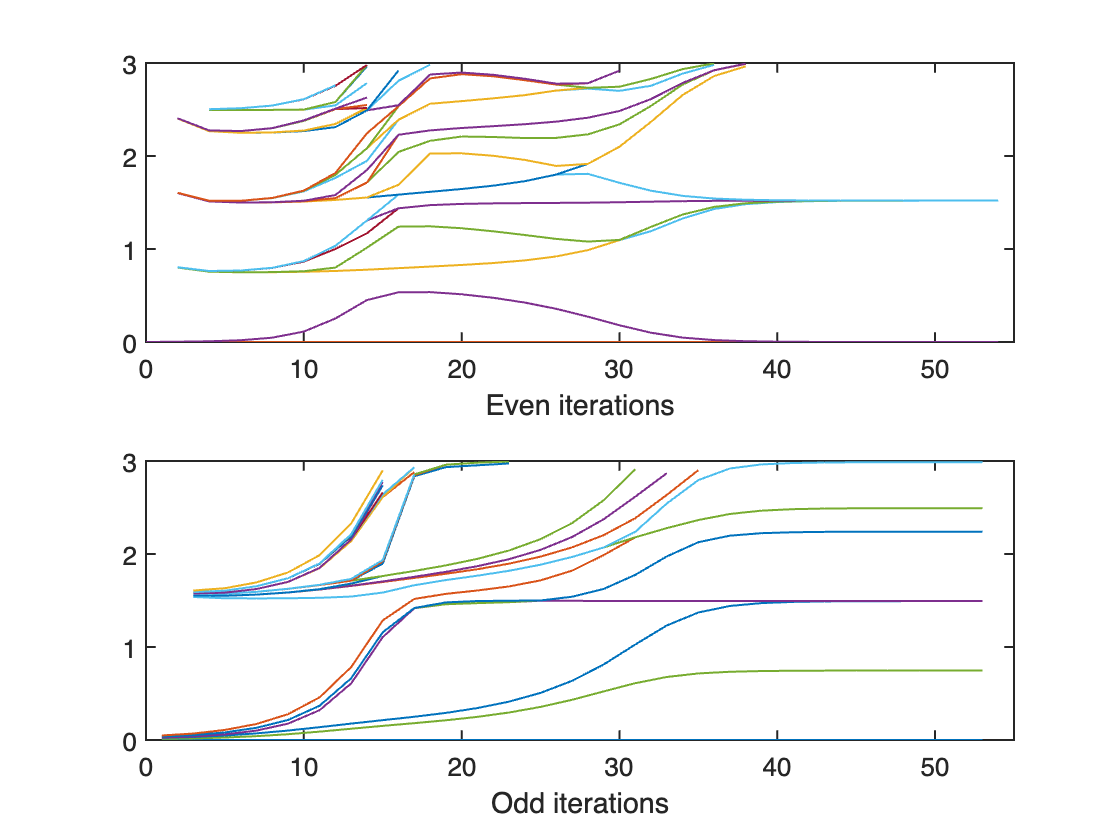


% Energy flow diagram
Eshow = 3; % energy window to show (from 0 to Eshow)

% since we start from A0; consider the step for H0 as 0, i.e., even
Eeven = Inrg.EK(1:2:end);
Eeven = cellfun(@(x) x(x <= Eshow), Eeven, 'UniformOutput', 0);
maxEeven = max(cellfun('prodofsize',Eeven));
Eeven = cellfun(@(x) [x;nan(maxEeven-numel(x),1)], Eeven, 'UniformOutput', 0);
Eeven = cell2mat(Eeven).';

Eodd = Inrg.EK(2:2:end);
Eodd = cellfun(@(x) x(x <= Eshow), Eodd, 'UniformOutput', 0);
maxEodd = max(cellfun('prodofsize',Eodd));
Eodd = cellfun(@(x) [x;nan(maxEodd-numel(x),1)], Eodd, 'UniformOutput', 0);
Eodd = cell2mat(Eodd).';

figure;
% upper panel
subplot(2,1,1);
plot((1:2:numel(Inrg.EK))-1,Eeven,'LineWidth',1);
xlabel('Even iterations');
xlim([0 numel(Inrg.EK)-1]);
ylim([0, Eshow]);
set(gca,'LineWidth',1,'FontSize',13);

% lower panel
subplot(2,1,2);
plot((2:2:numel(Inrg.EK))-1,Eodd,'LineWidth',1);
xlabel('Odd iterations');
xlim([0 numel(Inrg.EK)-1]);
ylim([0, Eshow]);
set(gca,'LineWidth',1,'FontSize',13);

The lowest-lying energies at iteration 53 (counting from iteration 0 for the impurity only) are:

fprintf([sprintf('%.4f, ',Inrg.EK{54}(1:5).'),'\n', ...
    sprintf('%.4f, ',Inrg.EK{54}(6:11).'),'...\n']);

0.0000, 0.7468, 0.7468, 0.7468, 0.7468, 
1.4937, 1.4937, 1.4937, 1.4937, 1.4937, 1.4937, ...


The fixed-point description for this iteration is that the impurity (site 0) and the first bath site (site 1) are strongly bound and the rest of the chain (from site 2 to site 53) are decoupled from the dimer. So the excitation spectrum is obtained by considering the lowest excitations of the single-particle Hamiltonian for the part from site 2 to site 53, having even number of sites.

[~,~,e_1p] = nonIntTB(-ff(3:53));
% factor (-1) due to convention in the function; 
% see line 26 of nonIntTB.m
e_1p = e_1p/Inrg.EScale(54);

% many-body energy values
Evs = [0; ... % ground-state
    e_1p(end/2+1); e_1p(end/2+1); ...
    % lowest one-particle excitation, spin-up/down
    -e_1p(end/2); -e_1p(end/2); ...
    % lowest one-hole excitation, spin-up/down
    e_1p(end/2+1)-e_1p(end/2); e_1p(end/2+1)-e_1p(end/2); ...
    e_1p(end/2+1)-e_1p(end/2); e_1p(end/2+1)-e_1p(end/2); ...
    % particle-hole pair excitation, up/down * up/down
    e_1p(end/2+1)*2; ...
    % two-particle exciation (up + down)
    -e_1p(end/2)*2];
    % two-hole exciation (up + down)
fprintf([sprintf('%.4f, ',Evs(1:5).'),'\n', ...
    sprintf('%.4f, ',Evs(6:11).'),'...\n']);

0.0000, 0.7469, 0.7469, 0.7469, 0.7469, 
1.4937, 1.4937, 1.4937, 1.4937, 1.4937, 1.4937, ...


On the other hand, the lowest-lying energies for iteration 54 have more degeneracies,

fprintf([sprintf('%.4f, ',Inrg.EK{55}(1:4).'),'\n', ...
    sprintf('%.4f, ',Inrg.EK{55}(5:12).'),'\n', ...
    sprintf('%.4f, ',Inrg.EK{55}(13:20).'),'...\n']);

0.0000, 0.0000, 0.0000, 0.0000, 
1.5205, 1.5205, 1.5205, 1.5205, 1.5205, 1.5205, 1.5205, 1.5205, 
1.5205, 1.5205, 1.5205, 1.5205, 1.5205, 1.5205, 1.5205, 1.5205, ...


The 4-fold and 16-fold degeneracies can be seen as that extra factor 4 is multiplied to the degeneracies of the 1-fold and 4-fold degeneratices in the case of iteration 53, putting aside different values of energies. This factor 4 can be understood by the fixed-point Hamiltonian as well. The part of the chain decoupled from the strongly coupled dimer has odd number of sites. So it has a zero mode:

[~,~,e_1p] = nonIntTB(-ff(3:54));
e_1p = e_1p/Inrg.EScale(55);
fprintf('%.4f\n',e_1p((end+1)/2));

0.0000


There are four Fock states regarding the zero mode (empty, spin-up, spin-down, doubly occupied), having all the same zero energy. So it introduces factor 4 to the degeneracies. Factoring out the degrees of freedom of this zero mode, we construct the lowest-lying energies at iteration 54 as for iteration 53:

% many-body energy values
Evs = [0; ... % ground-state
    e_1p((end+1)/2+1); e_1p((end+1)/2+1); ...
    % lowest one-particle excitation, spin-up/down
    -e_1p((end+1)/2-1); -e_1p((end+1)/2-1); ...
    % lowest one-hole excitation, spin-up/down
    e_1p((end+1)/2+1)-e_1p((end+1)/2-1); ...
    e_1p((end+1)/2+1)-e_1p((end+1)/2-1); ...
    e_1p((end+1)/2+1)-e_1p((end+1)/2-1); ...
    e_1p((end+1)/2+1)-e_1p((end+1)/2-1); ...
    % particle-hole pair excitation, up/down * up/down
    e_1p((end+1)/2+1)*2; ...
    % two-particle exciation (up + down)
    -e_1p((end+1)/2-1)*2];
    % two-hole exciation (up + down)
fprintf([sprintf('%.4f, ',Evs(1:5).'),'\n', ...
    sprintf('%.4f, ',Evs(6:11).'),'...\n']);

0.0000, 1.5205, 1.5205, 1.5205, 1.5205, 
3.0410, 3.0410, 3.0410, 3.0410, 3.0410, 3.0410, ...


## Solution to Exercise (c): Single-impurity Kondo model

In the example of the SIAM, we set the first leg (i.e., left leg) of `A0` as a dummy leg for vacuum and the second leg (i.e., bottom leg) for the Anderson impurity. The impurity Hamiltonian involves only one fermionic site (i.e., $d$ level). The rest of the chain Hamiltonian is the hopping and on-site terms that are generated within `NRG_IterDiag`.

On the other hand, in the SIKM, the exchange interaction $2J \hat{\vec{S}}_d \cdot \hat{\vec{S}}_0$ acts on two sites: a spin site for $\hat{\vec{S}}_d$ and a spinful fermionic site for $\hat{\vec{S}}_0$. The latter site is the first bath site, and coupled with the other fermionic sites via particle hopping that can be generated inside `NRG_IterDiag`.

Therefore, to use the same function `NRG_IterDiag` for the SIKM, we associate the first leg of `A0` with the spin site for $\hat{\vec{S}}_d$ and its second leg with the spinful fermionic site for $\hat{\vec{S}}_0$. Accordingly, we shift the hopping amplitudes and on-site energies by one site to the left, as the second leg of `A0` involves the first bath site.

clear

% Hamiltonian parameters
U = 4e-3; % Coulomb interaction at the impurity
epsd = -U/2; % impurity on-site energy
Delta0 = 2.5e-4; % hybridization strength
D = 1; % half-bandwidth
J = 8*Delta0/pi/U; % Kondo coupling strength
ozin = [-1;1]*D;
RhoV2in = [1;1];

Note that the prefactor to `RhoV2in` is not important, since it only affects `ff(1)` that is absorbed into the exchange interaction strength `J` via the Schrieffer–Wolff transformation (SWT).

% NRG parameters
Lambda = 2.5; % discretization parameter
N = 55; % length of the Wilson chain
Nkeep = 300;

% Wilson chain
[ff,gg] = doCLD(ozin,RhoV2in,Lambda,N);

% Construct local operators
[F,Z,S,I] = getLocalSpace('FermionS');
[Ss,Is] = getLocalSpace('Spin',1/2);

% particle number operator
NF = cat(3,contract(conj(F(:,:,1)),3,[1 3],F(:,:,1),3,[1 3]), ...
           contract(conj(F(:,:,2)),3,[1 3],F(:,:,2),3,[1 3]));

% ket tensor
A0 = getIdentity(Is,2,I,2,[1 3 2]);

% Impurity Hamiltonian
H0 = updateLeft(Ss,3,A0,permute(conj(S),[2 1 3]),3,A0);
% take the Hermitian conjugate to S
H0 = H0*(2*J);
H0 = H0 + gg(1)*updateLeft([],[],A0,sum(NF,3),2,A0);

Here the term proportional to `gg(1)` is added to `H0`. Since the contribution from `ff(1)` is absorbed into the exchange interaction via the SWT, we use `ff(2:end)` and `gg(2:end)` in the iterative diagonalization.

% iterative diagonalization
Inrg = NRG_IterDiag (H0,A0,Lambda,ff(2:end),F,gg(2:end),sum(NF,3),Z,Nkeep);

22-10-16 03:26:31 | NRG: start
22-10-16 03:26:31 | #00/54 : NK=8/8, EK=0.07958/0.07958
22-10-16 03:26:31 | #01/54 : NK=32/32, EK=3.231/3.231
22-10-16 03:26:31 | #02/54 : NK=128/128, EK=6.466/6.466
22-10-16 03:26:31 | #03/54 : NK=300/512, EK=6.987/13.1
22-10-16 03:26:31 | #04/54 : NK=328/1200, EK=6.853/12.86
22-10-16 03:26:31 | #05/54 : NK=316/1312, EK=6.891/13.64
22-10-16 03:26:31 | #06/54 : NK=328/1264, EK=6.819/12.8
22-10-16 03:26:32 | #07/54 : NK=310/1312, EK=6.814/13.54
22-10-16 03:26:32 | #08/54 : NK=328/1240, EK=6.84/12.77
22-10-16 03:26:32 | #09/54 : NK=314/1312, EK=6.89/13.46
22-10-16 03:26:32 | #10/54 : NK=328/1256, EK=6.911/12.88
22-10-16 03:26:32 | #11/54 : NK=322/1312, EK=7.007/13.42
22-10-16 03:26:33 | #12/54 : NK=317/1288, EK=6.912/13.18
22-10-16 03:26:33 | #13/54 : NK=300/1268, EK=6.965/13.16
22-10-16 03:26:33 | #14/54 : NK=302/1200, EK=7.146/13.09
22-10-16 03:26:33 | #15/54 : NK=312/1208, EK=7.324/13.32
22-10-16 03:26:34 | #16/54 : NK=310/1248, EK=7.703/13.81
22-10-16 0

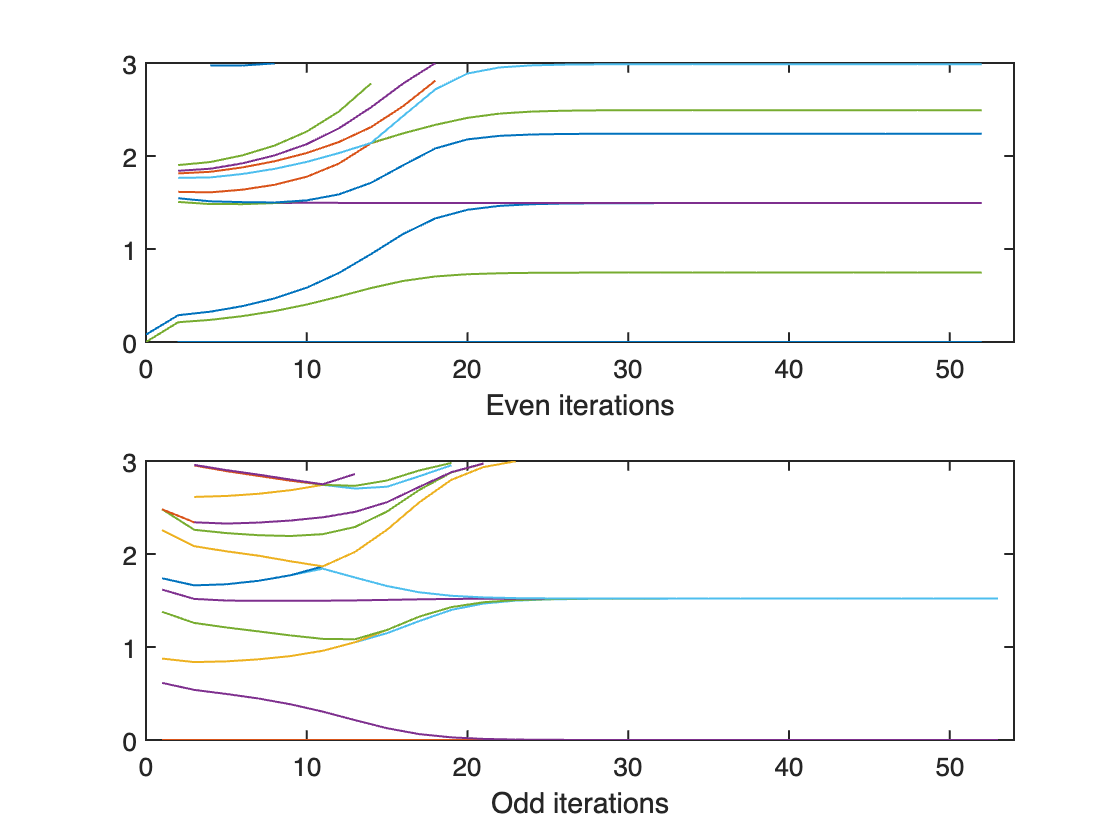

% Energy flow diagram
Eshow = 3; % energy window to show (from 0 to Eshow)

% since we start from A0; consider the step for H0 as 0, i.e., even
Eeven = Inrg.EK(1:2:end);
Eeven = cellfun(@(x) x(x <= Eshow), Eeven, 'UniformOutput', 0);
maxEeven = max(cellfun('prodofsize',Eeven));
Eeven = cellfun(@(x) [x;nan(maxEeven-numel(x),1)], Eeven, 'UniformOutput', 0);
Eeven = cell2mat(Eeven).';

Eodd = Inrg.EK(2:2:end);
Eodd = cellfun(@(x) x(x <= Eshow), Eodd, 'UniformOutput', 0);
maxEodd = max(cellfun('prodofsize',Eodd));
Eodd = cellfun(@(x) [x;nan(maxEodd-numel(x),1)], Eodd, 'UniformOutput', 0);
Eodd = cell2mat(Eodd).';

figure;
% upper panel
subplot(2,1,1);
plot((1:2:numel(Inrg.EK))-1,Eeven,'LineWidth',1);
xlabel('Even iterations');
xlim([0 numel(Inrg.EK)-1]);
ylim([0, Eshow]);
set(gca,'LineWidth',1,'FontSize',13);

% lower panel
subplot(2,1,2);
plot((2:2:numel(Inrg.EK))-1,Eodd,'LineWidth',1);
xlabel('Odd iterations');
xlim([0 numel(Inrg.EK)-1]);
ylim([0, Eshow]);
set(gca,'LineWidth',1,'FontSize',13);

The energy flow diagram looks similar with the diagram for the SIAM, especially the last crossovers and the spectrum at the last iterations in the strong-coupling fixed-point regime. There are two differences as well:

- The panel for even (odd) iterations in the SIKM case look similar to the panel for odd (even) iterations in the SIAM. It is because we have shifted the chain sites by one to the left.

- While there are two crossovers in the SIAM, here in the SIKM there is only one crossover, which is from the local moment regime to the Kondo regime.